k_t = 0.027;
mu_phi = 1.32e-6;
mu_theta = 8.82e-5;
J_phi = 2.3e-4;
J_theta = 0.029;
g = 9.8;
M = 0.982;
L = 1;
A = [0, 0, 1, 0;
    0, 0, 0, 1;
    0, 0, -mu_phi/J_phi, 0;
    0, -(M*g*L)/J_theta, mu_phi/J_theta, -mu_theta/J_theta];
B = [0; 0; k_t/J_phi; -k_t/J_theta];
C = [1, 0, 0, 0; 0, 1, 0, 0];
D = [0; 0];
[num, den] = ss2tf(A, B, C, D);

load('theta_cali.mat',"theta_cal");

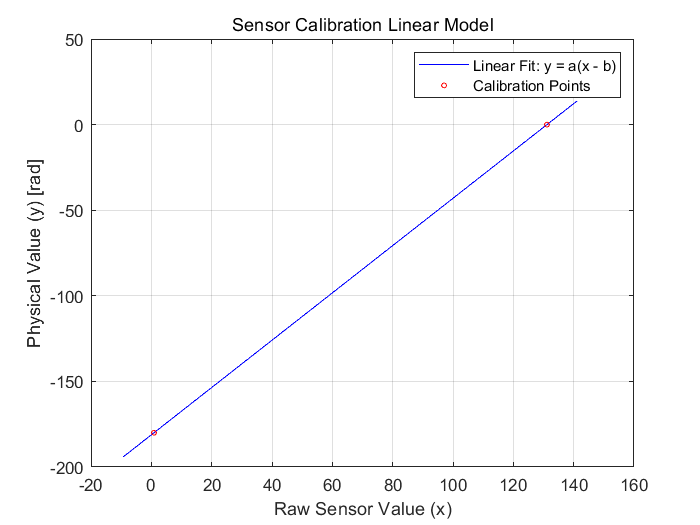

x1 = 0.86;
y1 = -180;
x2 = 131.13;
y2 = 0;

b = x2;                            
a = (y1) / (x1 - b);               

x_fit = linspace(x1 - 10, x2 + 10, 500);
y_fit = a * (x_fit - b);

figure;
plot(x_fit, y_fit, 'b-'); 
hold on;
plot([x1 x2], [y1 y2], 'ro', 'MarkerSize', 3);
grid on;

title('Sensor Calibration Linear Model');
xlabel('Raw Sensor Value (x)');
ylabel('Physical Value (y) [rad]');
legend('Linear Fit: y = a(x - b)', 'Calibration Points');


disp(['Model: y = ', num2str(a, '%.5f'), ' * (x - ', num2str(b, '%.2f'), ')']);

Model: y = 1.38175 * (x - 131.13)


% load('theta_square_0.5.mat',"theta");
% load('I_squre_0.5.mat','I');
% load('phidot_square_0.5.mat',"phidot");
load('squares1.mat');
theta_cal = calibrate_angle(theta, a, b);

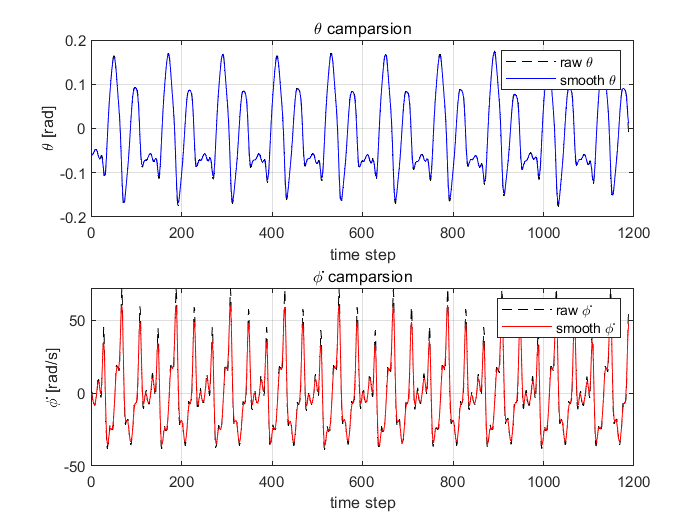

delay_estimate = 413;  
I_corrected = I_mot(delay_estimate+1:end);
theta_corrected = theta_cal(delay_estimate+1:end) - pi;
phidot_corrected = phidot(delay_estimate+1:end);

y_raw = [theta_corrected, phidot_corrected]; 
y = smoothdata(y_raw, 'movmean', 5);
u = I_corrected;                          

figure;

subplot(2,1,1);
plot(y_raw(:,1), 'k--'); 
hold on;
plot(y(:,1), 'b');
legend('raw \theta', 'smooth \theta');
title('\theta camparsion');
xlabel('time step'); ylabel('\theta [rad]');
grid on;

subplot(2,1,2);
plot(y_raw(:,2), 'k--'); 
hold on;
plot(y(:,2), 'r');
legend('raw \phi̇', 'smooth \phi̇');
title('\phi̇ camparsion');
xlabel('time step'); ylabel('\phi̇ [rad/s]');
grid on;


N = length(u);
split_point = floor(2 * N / 3);  

u_train = u(1:split_point);
y_train = y(1:split_point, :);

u_val = u(split_point+1:end);
y_val = y(split_point+1:end, :);

% s = 20;  
% 
% N = size(u_train, 1);  
% m = size(u_train, 2); 
% l = size(y_train, 2);  
% 
% K = N - 2*s + 1;  
% 
% U_p = zeros(s * m, K);
% U_f = zeros(s * m, K);
% Y_p = zeros(s * l, K);
% Y_f = zeros(s * l, K);
% 
% for i = 1:K
%     % Past inputs
%     U_p(:, i) = reshape(u_train(i:i+s-1, :)', [], 1);
%     % Future inputs
%     U_f(:, i) = reshape(u_train(i+s:i+2*s-1, :)', [], 1);
%     
%     % Past outputs
%     Y_p(:, i) = reshape(y_train(i:i+s-1, :)', [], 1);
%     % Future outputs
%     Y_f(:, i) = reshape(y_train(i+s:i+2*s-1, :)', [], 1);
% end
% 
% Z = [U_p; Y_p];
% UFYZ = [U_f; Z; Y_f];
% 
% [L, Q] = qr(UFYZ', 0);
% L_act = Q';
% 
% row_start = size(U_f, 1) + size(Z, 1) + 1;
% col_start = size(U_f, 1) + 1;
% L_32 = L_act(row_start:end, col_start:col_start + size(Z, 1) - 1);
% 
% singular_values = svd(L_32);
% 
% figure;
% semilogy(singular_values, 'o-');
% grid on;
% xlabel('Index');
% ylabel('Singular Value (Log Scale)');
% title('Singular Values of L_{32} (PI-MOESP)');

% n = 4;
% [A, B, C, D, x0] = pomoesp(u_train, y_train, s, n);
% [yhat_toy,xhat_toy] = simsystem(A, B, C, D, x0, u_train);
% vaf_toy = VAF(y_train,yhat_toy)
% rmse_toy = RMSE(y_train,yhat_toy)

data_id = iddata(y_train, u_train, 'Ts', 0.05);
opt = greyestOptions;
opt.InitialState = [-0.06; -0.46; 0];
params_lin_init = {'J_theta', 0.029; 'mu_theta', 8.82e-5; 'J_phi', 2.3e-4; 'mu_phi', 1.32e-6;
    'kt', 0.027; 'M', 1.104; 'L', 0.15;  'g', 9.81};

linear_model = idgrey('linear_reaction_pendulum', params_lin_init, 'c');
linear_model.Structure.Parameters(8).Free = false;
sys = greyest (data_id, linear_model, opt)

sys =
  Continuous-time linear grey box model defined by "linear_reaction_pendulum" function:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3
   x1         0         0         1
   x2         0    -1.362         0
   x3    -85.02  0.002354   -0.5501
 
  B = 
            u1
   x1        0
   x2    195.7
   x3  -0.3381
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
 
  Model parameters:
   J_theta = 0.02199
   mu_theta = 0.01209
   J_phi = 3.8e-05
   mu_phi = 5.176e-05
   kt = 0.007434
   M = 1.107
   L = 0.1722
   g = 9.81
 
Parameterization:
   ODE Function: linear_reaction_pendulum
   Disturbance component: none
   Initial state: fixed to double value
   Number of free coefficients: 7
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                     

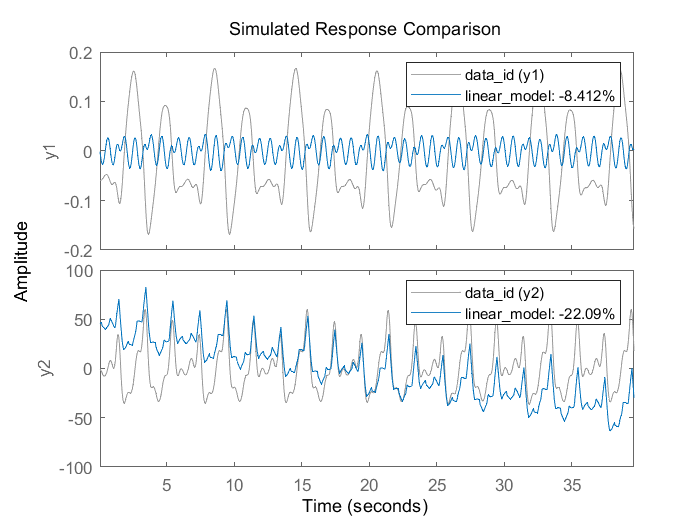

figure;
compare(data_id,linear_model)

Order = [2 1 3];   % [#outputs, #inputs, #states]
Ts = 0.05;              
kt = 0.027;
mu_phi = 1.32e-6;
mu_theta = 8.82e-5;
J_phi = 2.3e-4;
J_theta = 0.029;
g = 9.81;
M = 1.104;
L = 0.15;


parameters    = {J_theta, mu_theta, J_phi, mu_phi, kt, M, L, g};

initial_states = [-0.06; -0.46; 0];
nlgr = idnlgrey('reaction_pendulum_model', Order, parameters, initial_states, Ts);
setpar(nlgr,'Fixed',{true true true true true false false true});
data = iddata(y_train, u_train, 'Ts', 0.05);

% nlgr.Parameters(1).Fixed = true;
% nlgr.Parameters(4).Fixed = true;
% nlgr.Parameters(5).Fixed = true;

% opt = nlgreyestOptions;
% opt.Display = 'on';
% %opt.SearchMethod = 'lsqnonlin';  
% opt.SearchOptions.MaxIterations = 100;

estimated_model = nlgreyest(data, nlgr,'Display','Full')

estimated_model =
Discrete-time nonlinear grey-box model defined by 'reaction_pendulum_model' (MATLAB file):

   x(t+Ts) = F(t, u(t), x(t), p1, ..., p8)
      y(t) = H(t, u(t), x(t), p1, ..., p8) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 2 free parameter(s) (out of 8).

Sample time: 0.05 seconds

Status:                                                                                 
Estimated using Solver: FixedStepDiscrete; Search: lsqnonlin on time domain data "data".
Fit to estimation data: [-4.379e+04;-251.8]%                                            
FPE: 1.036e+07, MSE: 8222


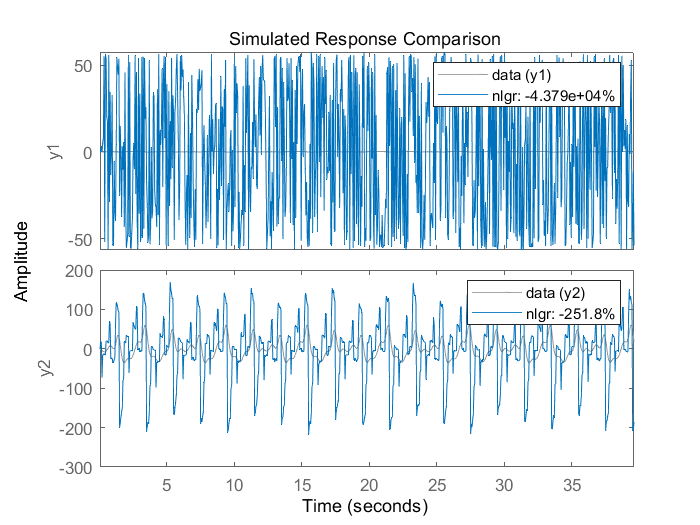

% 
% getpvec(estimated_model)
figure;
compare(data,nlgr)

function theta_cal = calibrate_angle(theta_raw, a, b)

theta_deg = theta_raw * (180 / pi);

theta_cal_deg = a * (theta_deg - b);

theta_cal = theta_cal_deg * (pi / 180);
end

% 
% function [A,B,C,D,x0]=pomoesp(u,y,s,n)
% % Instructions:
% % Implement your subspace ID method here.
% % Use the following function inputs and outputs.
% 
% % Function INPUT 
% % u         system input (matrix of size N x m)
% % y         system output (matrix of size N x l)
% % s         block size (scalar)
% %
% % Function OUTPUT
% % A         System matrix A (matrix of size n x n)
% % B         System matrix B (matrix of size n x m)
% % C         System matrix C (matrix of size l x n)
% % D         System matrix D (matrix of size l x m)
% % x0        Initial state (vector of size n x one)
% 
% % YOUR CODE HERE   
% 
% % end_train = floor(length(y)*2/3); 
% % 
% % y_train = y(1:end_train);
% % u_train = u(1:end_train);
% N_u = length(u);
% 
% m = size(u, 2);   
% l = size(y, 2);   
% 
% K = N_u - 2*s + 1;
% 
% U_p = zeros(s * m, K); 
% U_f = zeros(s * m, K); 
% Y_p = zeros(s * l, K); 
% Y_f = zeros(s * l, K);
% 
% 
% for i = 1:K
%     U_p(:, i) = reshape(u(i:i+s-1, :)', [], 1);
%     Y_p(:, i) = reshape(y(i:i+s-1, :)', [], 1);
%     U_f(:, i) = reshape(u(i+s:i+2*s-1, :)', [], 1);
%     Y_f(:, i) = reshape(y(i+s:i+2*s-1, :)', [], 1);
% end
% 
% Z = [U_p; Y_p]; 
% UFYZ = [U_f; Z; Y_f]; 
% 
% [~, Q] = qr(UFYZ', 0); 
% L_act = Q';
% row_start = size(U_f, 1) + size(Z, 1) + 1; 
% col_start = size(U_f, 1) + 1;              
% L_32 = L_act(row_start:end, col_start:col_start + size(Z, 1) - 1);
% % singular_values = svd(L_32);
% 
% % figure;
% % semilogy(singular_values, 'o-'); 
% % grid on;
% % xlabel('Index');
% % ylabel('Singular Value (Log Scale)');
% % title('Singular Values of L_{32}');
% [U, ~, ~] = svd(L_32,'econ');
% 
% C = U(1:l, 1:n);  
% A = U(1:end - 1, 1:n) \ U(2:end, 1:n);
% [N, m] = size(u); 
% [~, l] = size(y);
% 
% Phi = []; 
% Y_vec = []; 
% 
% for k = 1:N
%     CAk = C * (A^(k-1));
% 
%     sum_term = zeros(l, n*m); 
%     for j = 0:(k-1)
%         sum_term = sum_term + kron(u(j+1, :)', C * (A^(k-1-j)));
%     end
% 
%     D_term = kron(u(k, :), eye(l));
% 
%     Phi_k = [CAk, sum_term, D_term];
%     Phi((k-1)*l+1:k*l, :) = Phi_k;
% 
%     Y_vec((k-1)*l + 1 : k*l, 1) = y(k, :)';
% end
% Phi_m = zeros(N * l, n + n * m + l * m);
% Phi_m(:, 1:n) = Phi(:, 1:n);
% Phi_m(:, n+n*m+1:n+n*m+m) = Phi(:, n+n*m+1:n+n*m+m);
% Phi_m(l+1:N*l, n+1:n+n*m) = Phi(1:l*(N-1), n+1:n+n*m);
% Phi_m(1:l, n+1:n+n*m) = zeros(l, n*m);
% 
% Phi = Phi_m;
% theta = (Phi' *Phi)\Phi' * Y_vec; 
% 
% x0 = theta(1:n); 
% theta_B_start = n + 1;
% theta_B_end   = theta_B_start + n * m - 1;
% theta_D_start = theta_B_end + 1;
% 
% B = reshape(theta(theta_B_start:theta_B_end), [n, m]);
% D = reshape(theta(theta_D_start:end), [l, m]); 
% end
% 
% 
% function [y,x] = simsystem(A,B,C,D,x0,u)
% % Instructions:
% % Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% % initial condition x(0)
% %
% %
% % Function INPUT
% % A system matrix (matrix of size n x n)
% % B system matrix (matrix of size n x m)
% % C system matrix (matrix of size l x n)
% % D system matrix (matrix of size l x m)
% % x0 initial state (matrix of size n x one)
% % u system input (matrix of size N x m)
% %
% % Function OUTPUT
% % x state of system (matrix of size N x n)
% % y system output (matrix of size N x l)
% 
% % YOUR CODE HERE
% 
%     [N, ~] = size(u); 
%     n = size(A, 1); 
%     l = size(C, 1); 
% 
%     x = zeros(N, n); 
%     y = zeros(N, l); 
% 
%     x(1, :) = x0'; 
% 
%     for k = 1:N
% 
%         y(k, :) = (C * x(k, :)' + D * u(k, :)')'; 
% 
%         if k < N
%             x(k+1, :) = (A * x(k, :)' + B * u(k, :)')'; 
%         end
%     end
% end
% 
% 
% function vaf = VAF(y,yhat)
% % Instructions:
% % Implement the calculation of the VAF here.
% %
% % Function INPUT
% % y    measured system output (matrix of size N x l)
% % yhat simulated system output (matrix of size N x l)
% %
% % Function OUTPUT
% % VAF Variance Accounted For (scalar)
% 
% % YOUR CODE HERE
%     [~, l] = size(y);
%     vaf = zeros(1, l);
%     
%     for i = 1:l
%         num = norm(y(:, i) - yhat(:, i))^2;
%         den = norm(y(:, i) - mean(y(:, i)))^2;
%         vaf(i) = max(0, (1 - num / den) * 100);
%     end
% end
% 
% 
% 
% function rmse = RMSE(y,yhat)   
% % Instructions:
% % Implement the calculation of the RMSE here.
% %
% % Function INPUT
% % y    measured system output (matrix of size N x l)
% % yhat simulated system output (matrix of size N x l)
% %
% % Function OUTPUT
% % RMSE Root Mean Squared Error (scalar)
% 
% % YOUR CODE HERE
%     [~, l] = size(y);
%     rmse = zeros(1, l);
%     
%     for i = 1:l
%         rmse(i) = sqrt(mean((y(:, i) - yhat(:, i)).^2));
%     end
% end
% 
% 
% 
% function plot_toydata_results(y,yhat,vaf,rmse)
%     [~, l] = size(y);
%     figure;
% 
%     for i = 1:l
%         subplot(l, 1, i);
%         plot(y(:, i), 'b'); hold on;
%         plot(yhat(:, i), 'r--');
%         legend('Truth', 'Estimate');
%         title(sprintf('Output %d: VAF = %.2f%%, RMSE = %.4f', i, vaf(i), rmse(i)));
%         xlabel('Time step');
%         ylabel(sprintf('y_{%d}', i));
%         grid on;
%     end
% end


% function [dx, y] = reaction_pendulum_model(t, x, u, p)
%  
%     theta = x(1);
%     dphi = x(2);
%     dtheta = x(3);
% 
%     i = u(1);  
% 
%     J_theta = p(1);
%     mu_theta = p(2);
%     J_phi = p(3);
%     mu_phi = p(4);
%     kt = p(5);
%     M = p(6);
%     L = p(7);
%     g = 9.81;
% 
%     ddtheta = (-M*g*L*sin(theta) - mu_theta*dtheta + mu_phi*dphi - kt*i) / J_theta;
%     ddphi = (kt*i - mu_phi*dphi) / J_phi;
% 
%     dx = [dtheta; ddphi; ddtheta];
%     y = [theta; dphi];
% end
